# AI bias and fairness in MATLAB

## What is AI bias and fairness?

As AI is adopted in many industries, it started to impact daily lives with real life consequences, such as finance, education, employment, law enforcement, etc. As the result the issue of the bias has become frequent headlines in mainstream news. 

Typically, bias is used in AI in the context of the bias-variance tradeoff, but in this case, we are talking about more conventional sense that the system is biased against some protected class, such as race, gender, religion, age, disability, national origin, marital status, genetic information, etc. 

## Where does the AI bias come from?

Bias can creep into our AI models in every step of the way – from the data itself, in modeling, and in human review. For example, data we use may have overrepresented one class over other classes, or uses features that reflect our unconscious bias. Our hidden bias also affects how we choose to model the data, and evaluate the output from AI. Because we all have bias that we are not aware of, it is important to have diverse perspectives in your team as you collect data, develop models, and evaluate the outputs in order to catch our unconscious bias.

## How can we reduce AI bias?

How to ensure our AI models produce fairer and more equitable outcomes? This is still an active area of AI research and there is no perfect solutions yet. However, we do have some workable solutions that we can apply to very common binary classification problems, and they are available in Statistics and Machine Learning Toolbox in R2022b. 

## Define AI fairness

We can begin by defining AI fairness: if a model changes output based on sensitive attributes (i.e., race, gender, age, etc.), then it is biased; otherwise, it is fair.  

Simply removing sensitive characteristics from the dataset doesn't work because bias can be hidden in other predictors (i.e. zip code may correlate to race), and bias can creep into model as class imbalances in the training dataset as well during the training. Ideally, you want to 

- **Data-level**: evaluate the bias and fairness of the dataset before you begin the rest of the process

- **Model-level**: evaluate the bias and fairness of the predictions from the trained model

Statistical Parity Difference (SPD), and Disparate Impact (DI), can be used for both, while Equal Opportunity Difference (EOD), and Average Absolute Odds Difference (AAOD) are meant for evaluating model predictions. 

Let's try SPD on the built-in dataset patients. 

load patients
Gender = categorical(Gender);
Smoker = categorical(Smoker,logical([1 0]),["Smoker","Nonsmoker"]);
tbl = table(Diastolic,Gender,Smoker,Systolic);

We need to split the data into training set and test set and just use the training set. 

rng('default') % For reproducibility
cv = cvpartition(height(tbl),'HoldOut',0.3);
xTrain = tbl(training(cv),:);
xTest = tbl(test(cv),1:4);

Then use the training set to calculate the metrics. In this case, the positive class is 'nonsmoker' and SPD needs to be close to 0 in order for the dataset to be fair.


$$SPD=P(Y=Nonsmoker|Gender=Male) -P(Y=Nonsmoker|Gender=Female)\approx0$$


metrics = fairnessMetrics(xTrain,"Smoker",SensitiveAttributeNames="Gender");
metrics.PositiveClass

ans = categorical
     Nonsmoker 


report(metrics,BiasMetrics="StatisticalParityDifference")

ans = 2×3 table
    SensitiveAttributeNames    Groups    StatisticalParityDifference
    _______________________    ______    ___________________________

            Gender             Female                    0          
            Gender             Male               -0.31429          


This data-level evaluation shows that dataset is biased in favor of female nonsmoker than male nonsmoker. 

## Mitigate bias

Once we have ways to evaluate our dataset or model for bias and fairness, we can then use such metrics to mitigate the problem we find. Class imbalance is an issue for machine learning for a long time and many classifiers accepts weights (costs) to address this problem and it is easier to understand. 

Going back to the earlier example, let's calculate fairness weights and check the summary statistics. 

fairWeights = fairnessWeights(xTrain,"Gender","Smoker");
xTrain.Weights = fairWeights;
groupsummary(xTrain,["Gender","Smoker"],"mean","Weights")

ans = 4×4 table
    Gender     Smoker      GroupCount    mean_Weights
    ______    _________    __________    ____________

    Female    Smoker            5              2.1   
    Female    Nonsmoker        30          0.81667   
    Male      Smoker           16          0.65625   
    Male      Nonsmoker        19           1.2895   


In this dataset, female nonsmoker and male smoker are overrepresented and fairness weights discount these subgroups, while boosting other underrepresented subgroups. When we apply the weights to SPD calculation, you see that the results are much closer to 0. 

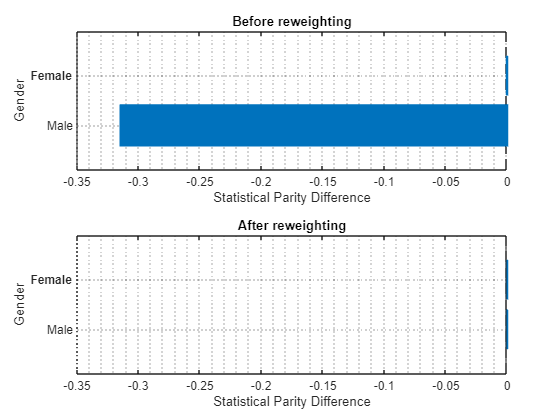

weightedMetrics = fairnessMetrics(xTrain,"Smoker",SensitiveAttributeNames="Gender",Weights="Weights");
figure
tiledlayout(2,1);
nexttile
plot(metrics,"StatisticalParityDifference")
title("Before reweighting")
xlabel("Statistical Parity Difference")
xl = xlim;
nexttile
plot(weightedMetrics,"StatisticalParityDifference")
title("After reweighting")
xlabel("Statistical Parity Difference")
xlim(xl);

## Using weights to train a fairer model

We can then use the fairness weights to train any binary classifiers, e.g. [fitcsvm](https://www.mathworks.com/help/stats/fitcsvm.html), [fitclinear](https://www.mathworks.com/help/stats/fitclinear.html), [fitctree](https://www.mathworks.com/help/stats/fitctree.html), [fitcknn](https://www.mathworks.com/help/stats/fitcknn.html), [fitcnet](https://www.mathworks.com/help/stats/fitcnet.html), [fitcensemble](https://www.mathworks.com/help/stats/fitcensemble.html), [fitckernel](https://www.mathworks.com/help/stats/fitckernel.html), etc., to develop more balanced models. Let's try `fitctree`. 

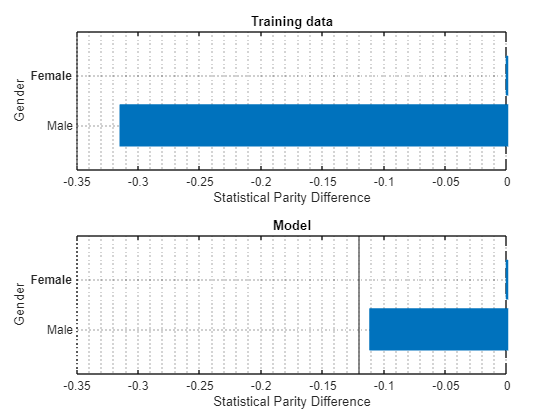

mdl = fitctree(xTrain,"Smoker",PredictorNames=["Diastolic","Gender","Systolic"],Weights="Weights");
yTest = predict(mdl,xTest);
trainMetrics = fairnessMetrics(xTrain,"Smoker",SensitiveAttributeNames="Gender");
modelMetrics = fairnessMetrics(xTest,"Smoker",SensitiveAttributeNames="Gender",Predictions=yTest);
figure
tiledlayout(2,1);
nexttile
plot(trainMetrics,"StatisticalParityDifference")
title("Training data")
xlabel("Statistical Parity Difference")
xl = xlim;
nexttile
plot(modelMetrics,"StatisticalParityDifference")
title("Model")
xlabel("Statistical Parity Difference")
xlim(xl);

The metrics shows that the trained model is closer to 0 in SPD than the training dataset.

## Closing

This was a quick introduction to the new AI bias and fairness features introduced in Statistics and Machine Learning Toolbox in R2022b.